omega_0 = 30;
K= 250;
b_f = 10;
m_e = 0.015;
b_e = 0.03;
b_f/omega_0

ans = 0.3333

eval(m_e_upper)

ans = 0.0014

collect(Z2,s)

$$ans = \frac{\left(b_{f}\,m_{e}\right)\,s^{3}+\left(K\,m_{e}+b_{e}\,b_{f}+b_{f}\,m_{e}\,\omega_{0}\right)\,s^{2}+\left(K\,b_{e}+K\,m_{e}\,\omega_{0}+b_{e}\,b_{f}\,\omega_{0}\right)\,s+K\,b_{e}\,\omega_{0}}{m_{e}\,s^{3}+\left(b_{e}+m_{e}\,\omega_{0}\right)\,s^{2}+\left(b_{e}\,\omega_{0}+b_{f}\,\omega_{0}\right)\,s+K\,\omega_{0}}$$

[numa dena]=numden(eval(Z2));
numa=eval(fliplr(coeffs(numa,s)));
dena=eval(fliplr(coeffs(dena,s)));
sys=tf([numa],[dena]);
[nume dene]=numden((Y_e));
nume=[1 0];
dene=eval(fliplr(coeffs(dene,s)));
env=tf([nume 0],dene);
zenv=tf([dene 0],[nume])


zenv =
 
  0.015 s^2 + 0.03 s
  ------------------
          s
 
Continuous-time transfer function.



eval(eqn_set)

ans = 1×3 logical array
   1   0   0


eval([eqn4 eqn5])

ans = 1×2 logical array
   1   0


eval(routh)

ans = 	1.0e+03 *

    0.0002    0.4299
    0.0090    7.7250
    0.2887         0
    7.7250         0


eval(aa1)

ans = 	1.0e+06 *

    1.6875
   -0.0254
   -0.0000
    0.0000


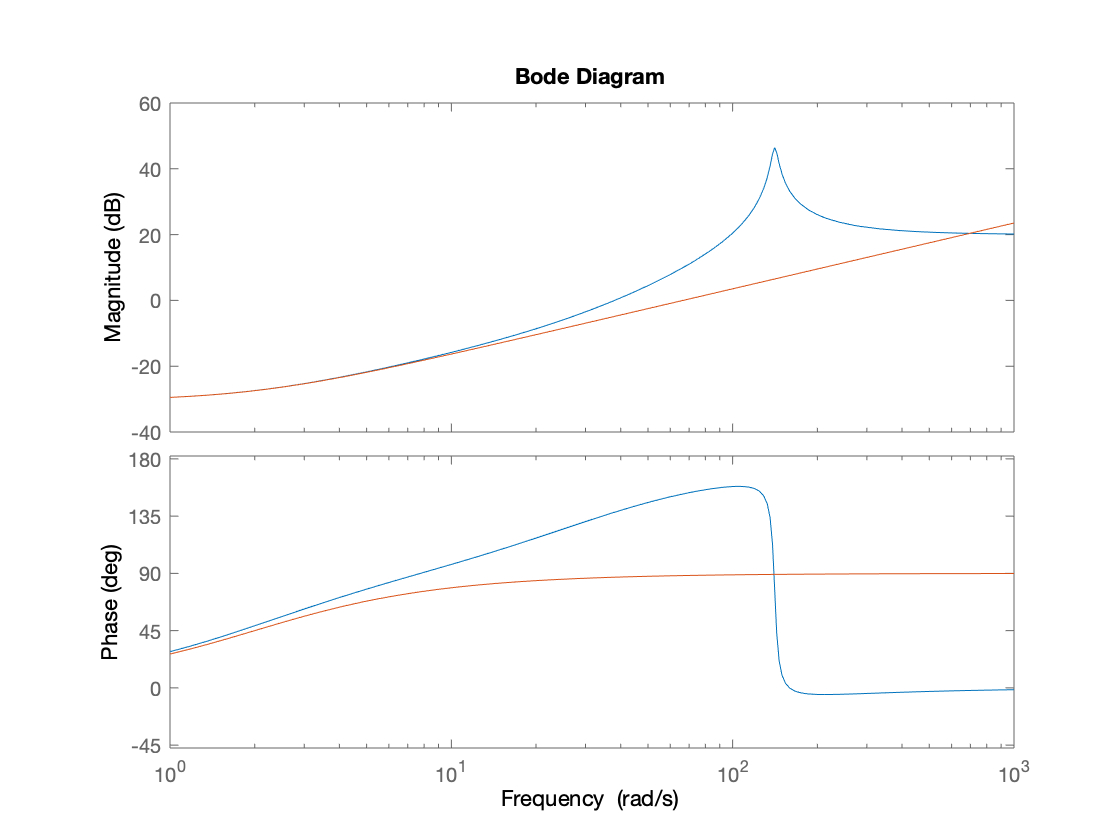

bode(sys,zenv,{1,1000})